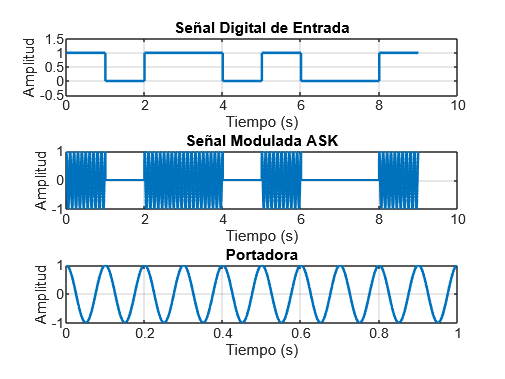

clc; clear; close all;

% Parámetros de la señal
Tb = 1;                % Duración de cada bit (en segundos)
fs = 1000;             % Frecuencia de muestreo (Hz)
fc = 10;               % Frecuencia de la portadora (Hz)
t = 0:1/fs:Tb-1/fs;    % Vector de tiempo para un bit
A1 = 1;                % Amplitud de la portadora cuando el bit es 1
A0 = 0;                % Amplitud de la portadora cuando el bit es 0

% Secuencia binaria a transmitir
bits = [1 0 1 1 0 1 0 0 1];  % Mensaje binario
N = length(bits);            % Número de bits
t_total = 0:1/fs:N*Tb-1/fs;  % Vector de tiempo total

% Generar la señal moduladora ASK
ask_signal = [];
for i = 1:N
    if bits(i) == 1
        ask_signal = [ask_signal, A1 * cos(2*pi*fc*t)];
    else
        ask_signal = [ask_signal, A0 * cos(2*pi*fc*t)];
    end
end

% Generar la señal digital original (para visualización)
digital_signal = repelem(bits, length(t));

% 📊 Graficar resultados
figure;
subplot(3,1,1);
stairs(t_total, digital_signal, 'LineWidth', 1.5);
ylim([-0.5 1.5]);
title('Señal Digital de Entrada');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

subplot(3,1,2);
plot(t_total, ask_signal, 'LineWidth', 1.5);
title('Señal Modulada ASK');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

subplot(3,1,3);
plot(t, cos(2*pi*fc*t), 'LineWidth', 1.5);
title('Portadora');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;